## Configuration_AES

Choose Key Standard: 

keyProperties = 128

keyProperties = 128

config = Config();
if keyProperties == 128
    config.Nk = 4;
    config.Nb = 4;
    config.Nr = 10;
elseif keyProperties == 192
    config.Nk = 6;
    config.Nb = 4;
    config.Nr = 12;
elseif keyProperties == 256
    config.Nk = 8;
    config.Nb = 4;
    config.Nr = 14;
end

SBox configuration:

sBoxConfig = "Test"

sBoxConfig = "Test"

if sBoxConfig == "Test"
    config.sBox = TestSBox();
    config.invSBox = TestInvSBox();
elseif sBoxConfig == "Random"
    config.sBox = SBox();
    config.invSBox = InvSBox();
end

Enter the plaintext and cipherkey:

plainText = "tuan"

plainText = "tuan"

plainText_rc4=plainText;
cipherKey = "letranquangtuan1"

cipherKey = "letranquangtuan1"

cipherKey_rc4=cipherKey;
textInts = uint8(char(plainText));
nblocks = int32(length(textInts)) / (config.Nb * 4);
npad = uint8(config.Nb * 4 ...
    - (length(textInts) - config.Nb * 4 * nblocks));
textInts = [textInts repmat(npad, 1, npad)]

textInts = 1×16 uint8 row vector
   116   117    97   110    12    12    12    12    12    12    12    12    12    12    12    12


keyInts = uint8(char(cipherKey));
npad = uint8(config.Nk*4 - length(keyInts));
keyInts = [keyInts repmat(npad, 1, npad)]

keyInts = 1×16 uint8 row vector
   108   101   116   114    97   110   113   117    97   110   103   116   117    97   110    49


config.K = keyInts;
tic;

## Encryption

cipherText = [];
for i = 1:(config.Nb * 4):length(textInts)
    fprintf("\n\n-----------------------------------------------------------------------\n");
    fprintf("Process for blob %i:", int32(i/(config.Nb * 4) + 1));
    fprintf("\n-----------------------------------------------------------------------\n");
    blob = Cipher( ...
        textInts(i:i+config.Nb * 4-1), ...
        config.K, ...
        config.Nk, ...
        config.Nb, ...
        config.Nr ...
    );
    cipherText = [cipherText blob];
end



-----------------------------------------------------------------------


Process for blob 1:


-----------------------------------------------------------------------




Initial Round: 
Initial State  :74 75 61 6e c c c c c c c c c c c c 
FirstRoundKey  : 6c 65 74 72 61 6e 71 75 61 6e 67 74 75 61 6e 31 
State          :18 10 15 1c 6d 62 7d 79 6d 62 6b 78 79 6d 62 3d 

Round 1: 
SubBytes      : ad ca 59 9c 3c aa ff b6 3c aa 7f bc b6 3c aa 27 
ShiftRows     : ad aa 7f 27 3c aa aa 9c 3c 3c 59 b6 b6 ca ff bc 
MixColumns    : fc 44 90 77 ab a 66 67 d3 19 73 56 71 9f 46 97 
RoundKey      : 82 fa b3 ef e3 94 c2 9a 82 fa a5 ee f7 9b cb df 
AddRoundKey   : 7e be 23 98 48 9e a4 fd 51 e3 d6 b8 86 4 8d 48 

Round 2: 
SubBytes      : f3 ae 26 46 52 b 49 54 d1 11 f6 6c 44 f2 5d 52 
ShiftRows     : f3 b f6 52 52 11 5d 46 d1 f2 26 54 44 ae 49 6c 
MixColumns    : 44 b6 f9 57 8c d1 33 36 c6 10 93 14 44 b4 cc f3 
RoundKey      : 94 e5 2d 87 77 71 ef 1d f5 8b 4a f3 2 10 81 2c 
AddRoundKey   : d0 53 d4 d0 fb a0 dc 2b 33 9b d9 e7 46 a4 4d df 

Round 3: 
SubBytes      : 70 ed 48 70 f e0 86 f1 c3 14 35 94 5a 49 e3 9e 
ShiftRows     : 70 e0 35 9e f 14 e3 70 c3 49 48 f1 5a ed


aes_encry_time=toc

aes_encry_time = 1.1674


display(cipherText);

cipherText = 4×4 int16 matrix
    81   104   107   112
   173   249    42   172
   196   113     3    91
   192   120   132   137


## Decryption

decryptedInts = []; 
tic;
for i = 1:(config.Nb * 4):length(textInts)
    fprintf("\n\n-----------------------------------------------------------------------\n");
    fprintf("Process for blob %i:", int32(i/(config.Nb * 4) + 1));
    fprintf("\n-----------------------------------------------------------------------\n");
    decryptedBlob = InvCipher( ...
        cipherText(i:i+config.Nb * 4-1), ...
        config.K, ...
        config.Nk, ...
        config.Nb, ...
        config.Nr ...
    );
    decryptedInts = [decryptedInts decryptedBlob];
end



-----------------------------------------------------------------------


Process for blob 1:


-----------------------------------------------------------------------




Initial Round: 
Initial State  :51 ad c4 c0 68 f9 71 78 6b 2a 3 84 70 ac 5b 89 
FirstRoundKey  : f3 7c 9 76 83 fb 33 ec 3a e9 97 9a 1 5e 6c 39 
State          :a2 d1 cd b6 eb 2 42 94 51 c3 94 1e 71 f2 37 b0 

Round 1: 
InvShiftRows  : a2 f2 94 94 eb d1 37 1e 51 2 cd b0 71 c3 42 b6 
InvSubBytes   : 1a 4 e7 e7 3c 51 b2 e9 70 6a 80 fc 2c 33 f6 79 
RoundKey      : 6c 70 b9 3b 73 87 12 b7 3 3a a4 fb 94 9a 76 a3 
AddRoundKey   : 76 77 e4 73 4c d6 88 73 c9 78 24 8a 17 84 d da 
InvMixColumns : 40 10 e5 23 1a 8c 1c eb ce c2 1d e 10 bc 82 6a 

Round 2: 
InvShiftRows  : 40 bc 1d eb 1a 10 82 e ce 8c e5 6a 10 c2 1c 23 
InvSubBytes   : 72 78 de 3c 43 7c 11 d7 ec f0 2a 58 7c a8 c4 32 
RoundKey      : 71 1c c9 82 bc f4 95 a5 0 39 9e 5f 87 e ec d5 
AddRoundKey   : 3 c4 de bb 5f 88 28 d9 25 65 b4 b4 fe d 9b e7 
InvMixColumns : a d2 88 f2 20 81 1b 9c a1 c3 b0 92 17 24 77 cb 

Round 3: 
InvShiftRows  : a 24 b0 9c 20 d2 77 92 a1 81 88 cb 17 c3 1b f2 
InvSubBytes   : a3 a6 fc 1c 54 7f 2 74 f1 91 97 59 87 

aes_decry_time=toc

aes_decry_time = 0.4712

decryptedInts = decryptedInts(:);
if range(decryptedInts(end-decryptedInts(end)+1:end)) == 0
    fprintf("Decryption successful!\nPlain text: %s", ...
        char(decryptedInts(1:end-decryptedInts(end))));
else
    fprintf("Decryption failed :(");
end

Decryption successful!
Plain text: tuan

key = 'letranquangtuan1';
plaintext = 'tuan'

plaintext = 'tuan'

%plainText_rc4
[a,b] = rc4_test(plaintext,key);

a = 1×16 uint16 row vector
   108   101   116   114    97   110   113   117    97   110   103   116   117    97   110    49


rc4_time_encrypt 0.011121

res_in_hex = '['E6';'E1';'9E';'5A']'

res_in_unicode = 'æáZ'

a = 1×16 uint16 row vector
   108   101   116   114    97   110   113   117    97   110   103   116   117    97   110    49


rc4_time_decrypt 0.042217

res_in_hex = '['74';'75';'61';'6E']'

res_in_unicode = 'tuan'

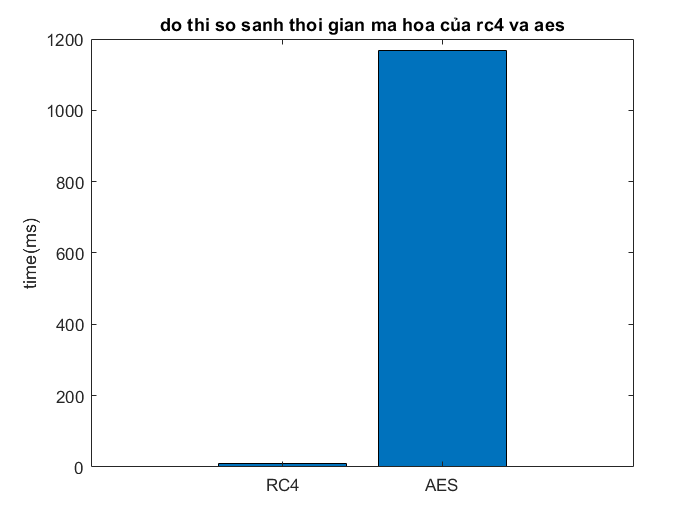

xlabels = {'RC4', 'AES'};
a=a*1000;
aes_encry_time=aes_encry_time*1000;
ydata = [a aes_encry_time];
bar(ydata);
set(gca, 'xticklabel', xlabels);
ylabel('time(ms)');
title('do thi so sanh thoi gian ma hoa của rc4 va aes');

xlabels = {'RC4', 'AES'};
b=b*1000;
aes_decry_time=aes_decry_time*1000;
ydata = [b aes_decry_time];
bar(ydata);
heso=aes_decry_time/b

heso = 11.1607

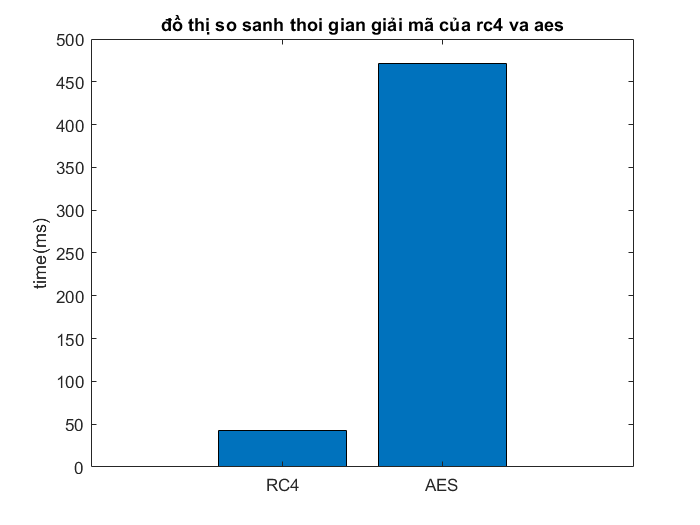

set(gca, 'xticklabel', xlabels);
ylabel('time(ms)');
title('đồ thị so sanh thoi gian giải mã của rc4 va aes');